save_name = "manchester_depth_3";
black_list = ["research.manchester.ac.uk"];
[adjacency_matrix, node_labels] = webCrawler("https://www.manchester.ac.uk", 3, 2000, black_list)

==================================================]


adjacency_matrix = 1821×1821 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0 

node_labels = 1×1821 cell array
  Columns 1 through 399

    {' https://bjgp.o…'}    {'http://app.manc…'}    {'http://blog.gdi…'}    {'http://blog.pol…'}    {'http://blog.pol…'}    {'http://chokkan.…'}    {'http://dembinsk…'}    {'http://director…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://document…'}    {'http://doi.org/…'}    {'http://estatesa…'}    {'http://estatesa…'}    {'http://events.m…'}    {'http://feeds.fe…'}    {'http://givingbl…'}    {'http://gofund.m…'}    {'http://intranet…'}    {'http://journals…'}    {'http://ktp.inno…'}    {'http://luna.man…'}    {'http://molymem.…'}    {'http://my.manch…'}    {'http://open.wei…'}    {'http://paypal.m…'}    {'h

save(save_name, 'adjacency_matrix', 'node_labels')

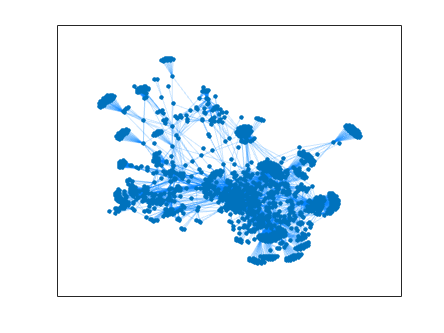

% Graph
figure;
graph = digraph(adjacency_matrix);
gp = plot(graph, 'layout', 'force','NodeLabel', {});
graph_plot = gp;
row = dataTipTextRow('label: ',node_labels);
gp.DataTipTemplate.DataTipRows(end+1) = row;
gp.EdgeColor = [0,0.5,1];
gp.EdgeAlpha = 0.2;
gp.ShowArrows = "off";